# Normalized Cross-Correlation

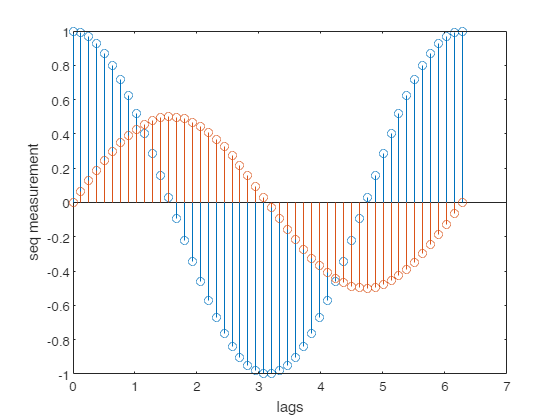

X = linspace(0,2*pi,50)';
Y = [cos(X), 0.5*sin(X)];
stem(X,Y)
[c,lags] = xcorr(Y(:,1),Y(:,2),'normalized');
xlabel('lags')
ylabel('seq measurement')

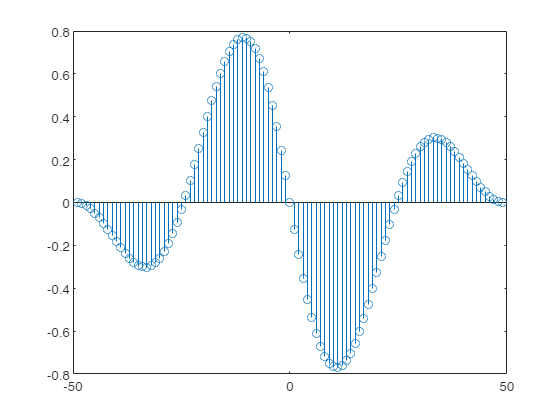

stem(lags,c)

[m_value, m_idx] = max(c);
m_idx

m_idx = 39

lags(m_idx)

ans = -11

line space

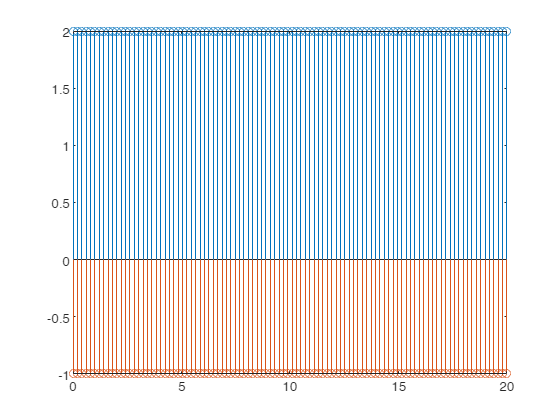

X = linspace(0, 20, 100)';
Y = [ones(size(X)) .* 2, ones(size(X)) .* -1];
stem(X,Y)

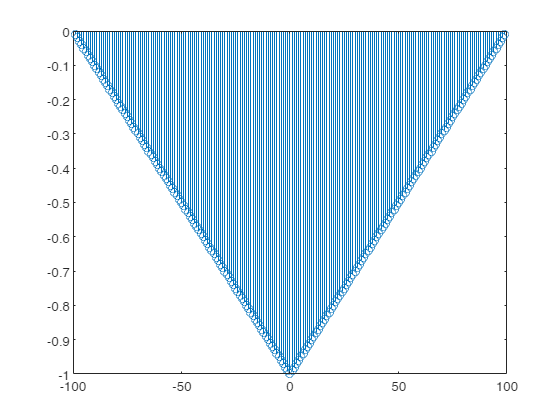

[c,lags] = xcorr(Y(:,1),Y(:,2),'normalize');
stem(lags, c)

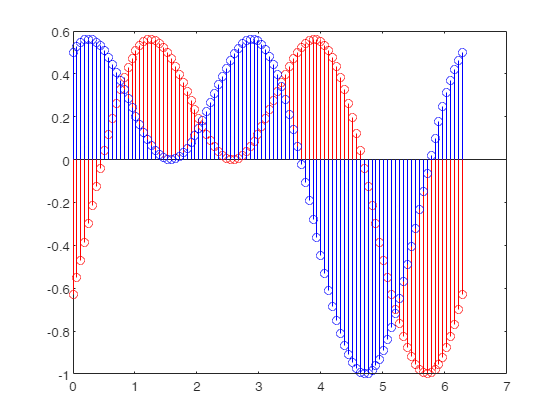

clf
X = linspace(0,2*pi,100)';
Y = [0.5*(sin(X-1)+cos((X-1)*2)), 0.5*(sin(X)+cos(X*2))];

xlabel('x')
ylabel('y')

stem(X, Y(:,1), 'r');
hold on;
stem(X, Y(:,2), 'b');
hold off;

[c,lags] = xcorr(Y(:,2),Y(:,1),'normalized');
[val ,idx]= max(c)

val = 0.9312

idx = 85

bestLag = lags(idx)

bestLag = -15

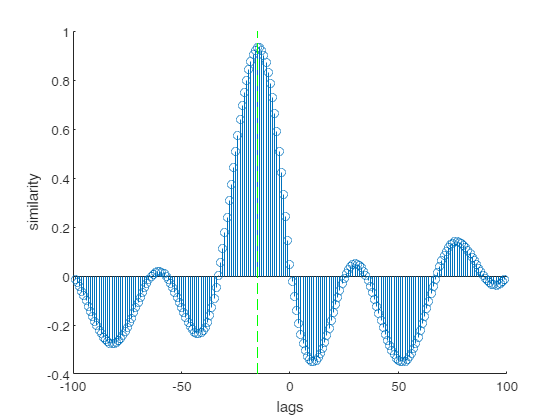

clf
hold on;
xlabel('lags')
ylabel('similarity')
stem(lags, c)
plot([bestLag bestLag], ylim, 'g--')
hold off;

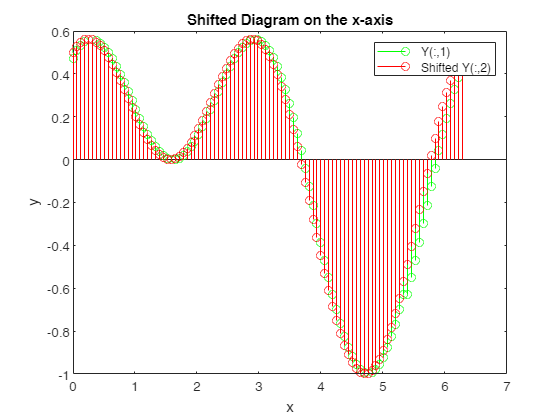


shiftedY = circshift(Y(:,1), bestLag);

stem(X, shiftedY, 'g');  % Plot Y(:,1) with blue markers
hold on;
stem(X, Y(:,2), 'r');  % Plot shifted Y(:,2) with red markers
hold off;

xlabel('x');
ylabel('y');
legend('Y(:,1)', 'Shifted Y(:,2)');
title('Shifted Diagram on the x-axis');

New experiment